# Curate Ripples

In this document, the use of RippleCurator for analysis of Ripples is documented

## Import libaries

Buzcode GitHub Repo

addpath(genpath("C:\Users\Linus Meienberg\Documents\Buzcode"));
addpath(genpath('C:\Users\Linus Meienberg\Documents\MultiAreaBundleProject\RippleAnalysis'))

## Script Parameters

output_dir = "D:\INI\SemesterArbeitBaran\rTBY33\7_freely_behav_220315_145519";
lfp.filename = 'D:\INI\SemesterArbeitBaran\rTBY33\7_freely_behav_220315_145519\amplifier_ds.dat';
lfp.samplerate = 2000;
lfp.num_channels = 256;
lfp.ripple_channels = [121,120,85,84,86,83,87,82,88,119]; % channel number of contigous sites that show ripples
lfp.main_channel = 1; % index of the main channel for ripple detection in lfp.ripple_channels

## Import LFP data

lfp.data = detrend(double(ImporterDAT_multi(lfp.filename,lfp.num_channels,lfp.ripple_channels))'); % detrend and subsequent op require (time,channels) format
lfp.timestamps = (1:size(lfp.data,1))/lfp.samplerate;

## Filter Data

bandpass = designfilt('bandpassfir','FilterOrder',600,'StopbandFrequency1',125,'PassbandFrequency1',130,'PassbandFrequency2',245,'StopbandFrequency2',250,'SampleRate',2000);
lowpass = designfilt('lowpassfir','FilterOrder',600,'PassbandFrequency',245,'StopbandFrequency',250,'SampleRate',2000);
lfp.bandpass = filtfilt(bandpass,lfp.data);
lfp.lowpass = filtfilt(lowpass,lfp.data);

## Load Ripple Events from manual annotation

load("D:\INI\SemesterArbeitBaran\RippleAnalysis\rTBY33_S7\rTBY33S7_DS0519_ripples.mat")

deleted = ripple_classes=='deleted';
if any(deleted)
    ripple_classes(deleted) = [];
    ripple_timestamps(deleted,:) = [];
    ripple_center_timestamps(deleted)=[];
end
ripples.clusterID = ripple_classes;
ripples.timestamps = ripple_timestamps;

load("C:\Users\Linus Meienberg\Documents\MultiAreaBundleProject\RippleAnalysis\RippleDetection\rTBY33S7_DS0505_manual.mat")
ripple_classes = categorical(ripple_classes,[0 1 2],{'SPWR','Ripple','false positive'}); % convert class ID to categorical labels
ripples.clusterID = [ripples.clusterID; ripple_classes]; 
ripples.timestamps = [ripples.timestamps; ripple_timestamps];

ripples.n = size(ripples.timestamps,1);

## Load Feature Table from manual annotation

load("D:\INI\SemesterArbeitBaran\RippleAnalysis\rTBY33_S7\rTBY33S7_DS0519_features.mat")
featureTableManual = featureTable;
ripples.centers = table2array(featureTableManual(:,'center Timepoint'));

## Spin up RippleCurator

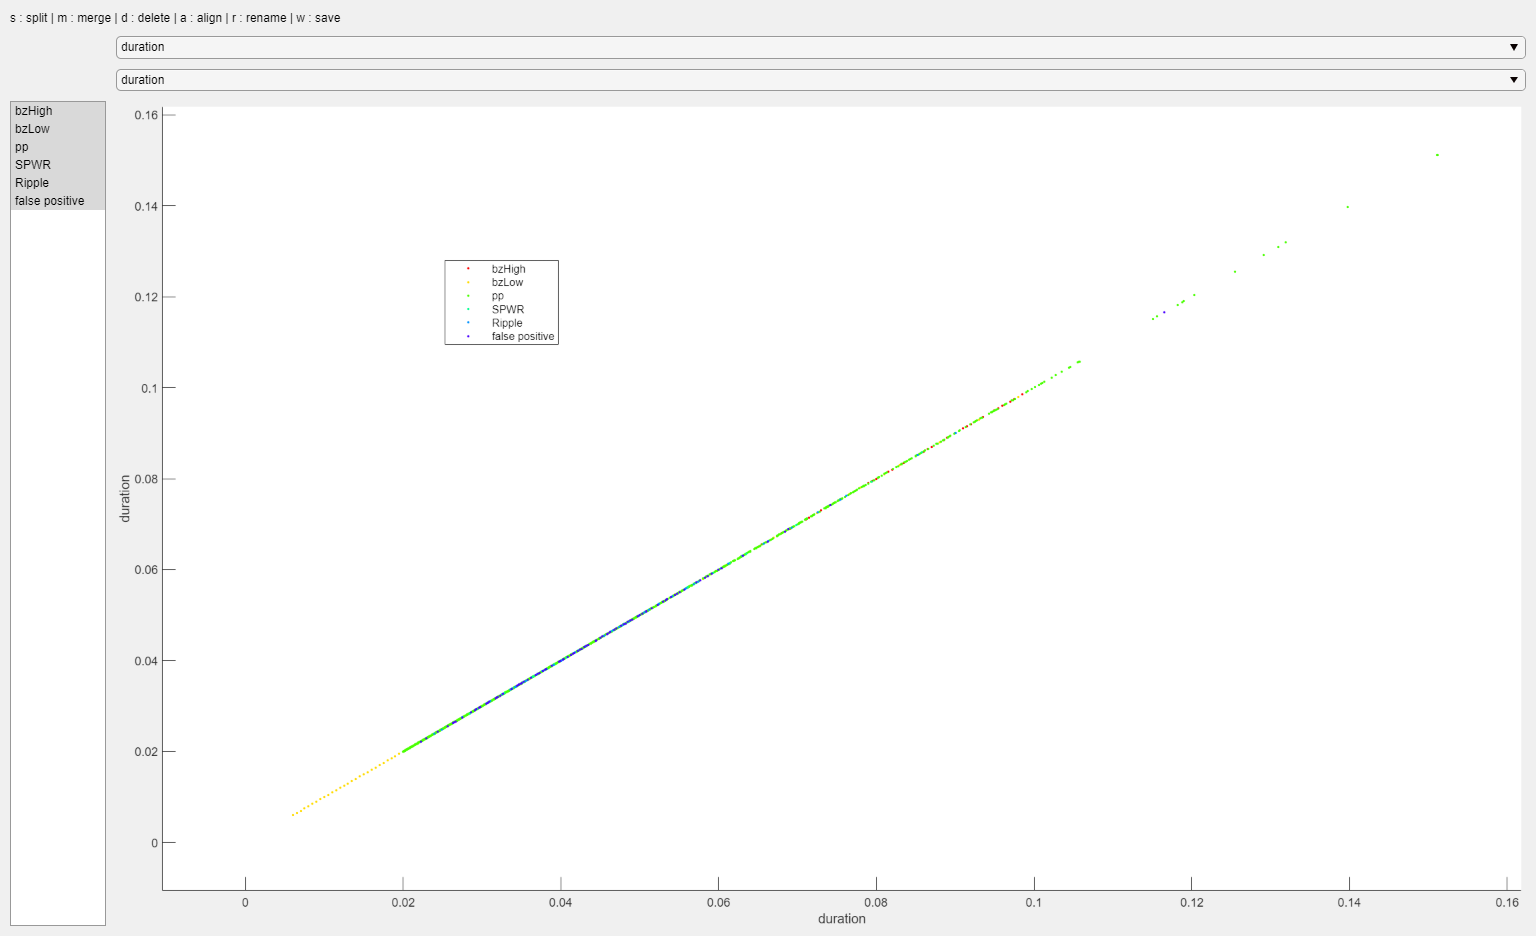

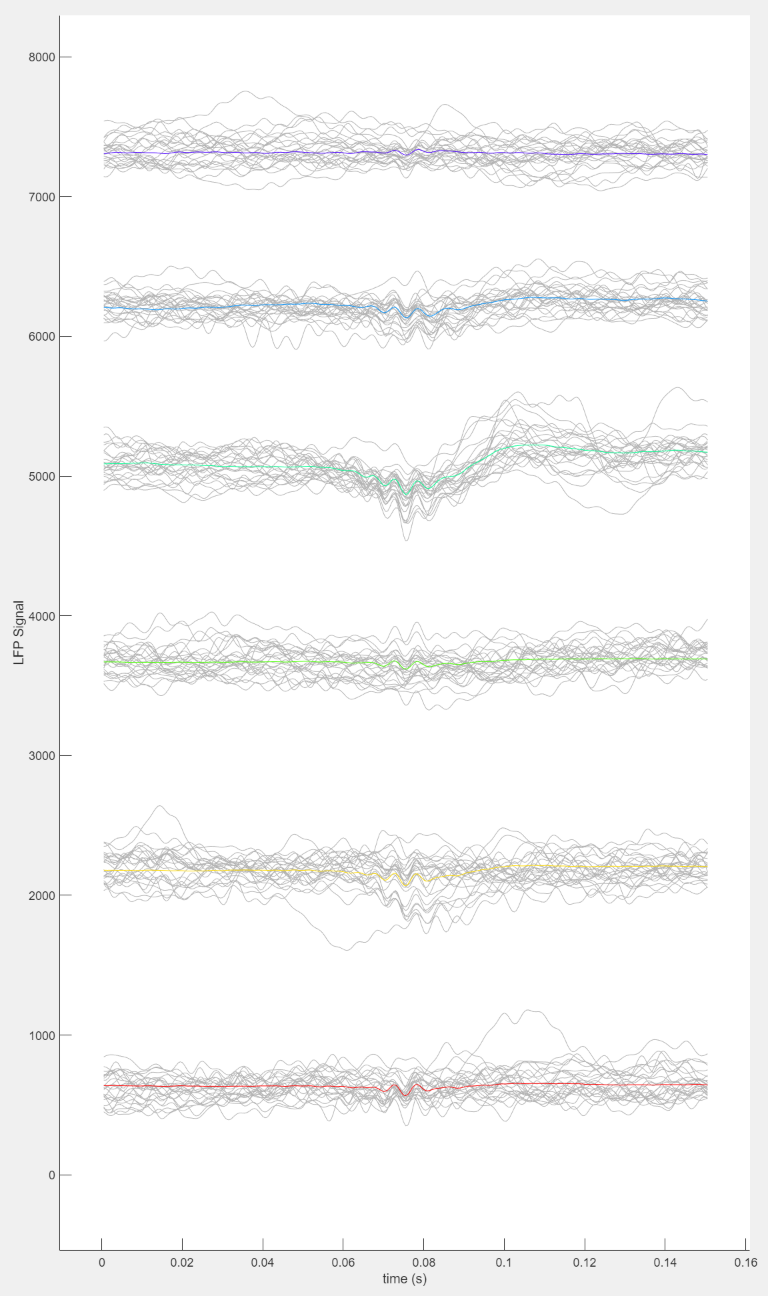

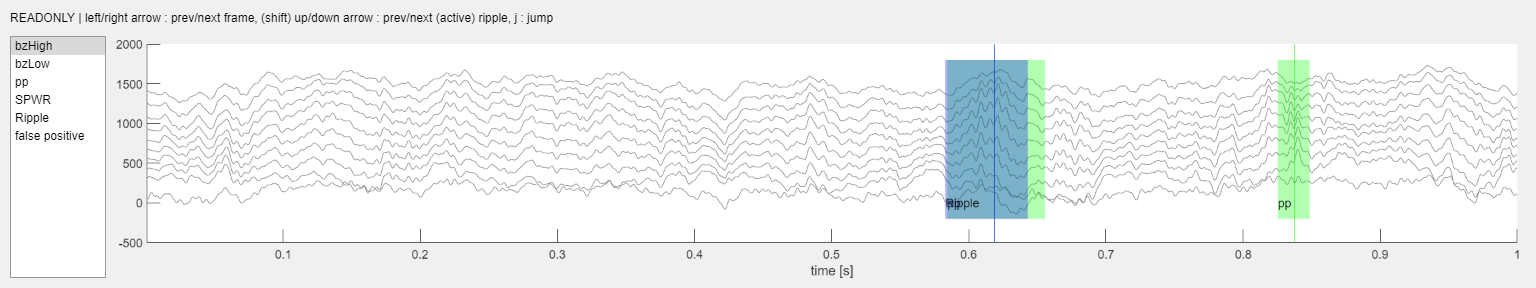

c = RippleCurator(2000,lfp.lowpass,ripples.timestamps,ripples.centers,ripples.clusterID,featureTableManual);